filename_thalamus = 'ClosedLoopPerformanceTest.h5';

squareWave = h5read(filename_thalamus, '/analog/Node 1/Dev2/ai0/data');
squareWaveTime = h5read(filename_thalamus, '/analog/Node 1/Dev2/ai0/received');
squareWaveTime = double(squareWaveTime(1,:))';
squareWaveTime = squareWaveTime/1e6; % Originally in nanoseconds so we convert to ms
squareWaveTimeFinal = squareWaveTime - squareWaveTime(1);

pulse = h5read(filename_thalamus, '/analog/Node 1/Dev2/ai1/data');
pulseTime = h5read(filename_thalamus, '/analog/Node 1/Dev2/ai1/received');
pulseTime = double(pulseTime(1,:))';
pulseTime = pulseTime/1e6;
pulseTimeFinal = pulseTime - squareWaveTime(1);

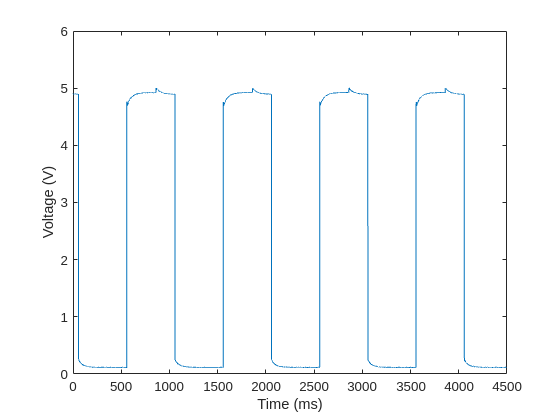

figure('Color','w')
plot(squareWaveTimeFinal,squareWave)
xlabel('Time (ms)')
ylabel('Voltage (V)')
xlim([0 4500])

threshold = 0.5;

diffSquareWave = diff(squareWave);

risingEdgeLogicalSquare = diffSquareWave > threshold;

% Get the indices where the rising edges occur.
% (Note: diff produces an array that is one element shorter, so we add 1 to align with the original signal.)
risingEdgeIndicesSquare = find(risingEdgeLogicalSquare) + 1;

% Extract the corresponding times from squareWaveTimeFinal
risingEdgeTimesSquare = squareWaveTimeFinal(risingEdgeIndicesSquare);

%% Detect rising edges in pulse
diffPulse = diff(pulse);
risingEdgeLogicalPulse = diffPulse > threshold;
risingEdgeIndicesPulse = find(risingEdgeLogicalPulse) + 1;
risingEdgeTimesPulse = pulseTimeFinal(risingEdgeIndicesPulse);

%% Align rising edges and compute lags
% It is assumed that the nth rising edge of squareWave corresponds to the nth rising edge of pulse.
% In case the number of detected rising edges differ, only compare the overlapping ones.
numEdges = min(length(risingEdgeTimesSquare), length(risingEdgeTimesPulse));
risingEdgeTimesSquare = risingEdgeTimesSquare(1:numEdges);
risingEdgeTimesPulse  = risingEdgeTimesPulse(1:numEdges);

% Compute lags: positive lag means squareWave lags behind pulse.
lags = risingEdgeTimesPulse - risingEdgeTimesSquare;

medianLag = median(lags);
minLag    = min(lags);
maxLag    = max(lags);
meanLag   = mean(lags);
stdLag    = std(lags);
skewLag   = skewness(lags);

fprintf('Rising Edge Lag Metrics:\n');
fprintf('-------------------------\n');
fprintf('Median lag: %.3f ms\n', medianLag);
fprintf('Minimum lag: %.3f ms\n', minLag);
fprintf('Maximum lag: %.3f ms\n', maxLag);
fprintf('Mean lag: %.3f ms\n', meanLag);
fprintf('Standard Deviation: %.3f ms\n', stdLag);
fprintf('Skewness: %.3f\n', skewLag);

Rising Edge Lag Metrics:


-------------------------


Median lag: 2.118 ms


Minimum lag: 1.980 ms


Maximum lag: 2.283 ms


Mean lag: 2.135 ms


Standard Deviation: 0.068 ms


Skewness: 0.057


skewLag = skewness(lags);


% Kolmogorov-Smirnov Test
[H_ks, p_ks] = kstest((lags - meanLag) / stdLag);
fprintf('Kolmogorov-Smirnov test p-value: %.5f\n', p_ks);

Kolmogorov-Smirnov test p-value: 0.45642


% Anderson-Darling Test
[H_ad, p_ad] = adtest(lags);
fprintf('Anderson-Darling test p-value: %.5f\n', p_ad);

Anderson-Darling test p-value: 0.25886


if (p_ks > 0.05) && (p_ad > 0.05)
    fprintf('Distribution is normal. Mean and Std Dev are appropriate.\n');
else
    fprintf('Distribution is not normal. Consider using median and IQR.\n');
end

if abs(skewLag) < 0.5
    fprintf('Skewness (%.3f) is low, indicating an approximately normal distribution.\n', skewLag);
elseif abs(skewLag) < 1
    fprintf('Skewness (%.3f) is moderate, indicating mild asymmetry.\n', skewLag);
else
    fprintf('Skewness (%.3f) is high, indicating a strongly skewed distribution.\n', skewLag);
end

Distribution is normal. Mean and Std Dev are appropriate.


Skewness (0.057) is low, indicating an approximately normal distribution.


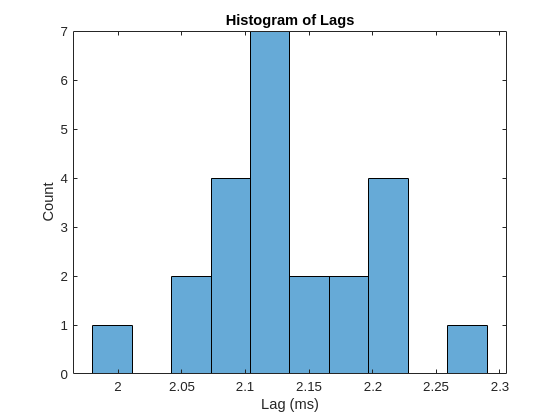

figure('Color','w'); histogram(lags, 10); xlabel('Lag (ms)'); ylabel('Count'); title('Histogram of Lags');